# Mathematical model for the sumoylation system

**Ref:** Puntambekar, S. S., Nyayanit, D., Saxena, P., & Gadgil, C. J. (2016). Identification of Unintuitive Features of Sumoylation through Mathematical Modeling. Journal of Biological Chemistry, 291(18), 9458-9468.

clc; clear all; close all;

**Cases considered for simulations are as follows:**

- **System having one (or two) proteins targeted for sumoylation**

- **To sumoylate E2 along with the target protein**

- **to simulate an open (long term events / in vivo) or closed (short term events / in vitro) system**

- **time course analysis **

- **steady state analysis**

Define the system you want to simulate by setting the parameters listed below.

systemhas2tars = 1;         %%% system with two proteins (targets) for sumoylation : ( 0=no | 1=yes )
e2istar = 0;                %%% sumoylation of E2 : ( 0=no | 1=yes )
isclosedsys = 0;            %%% closed system simulations ( 1 = closed | 0 = open system )
ss_analysis = 1;            %%% steady state analysis
timecourse_analysis = 1;    %%% time course simulations
toplot_timecourse_figs = 1; %%% figures displaying the time course system component's concentrations

getnames;
param=getparams_real;

%% For a closed system; setting the formation and degradation rate parameters to 0; 
%% and starting with some non-zero initial concentration of the proteins
if isclosedsys == 1
    y0=getinitialCLOSED(param);
    param.k(1:10,:)=0;   %%% for presumo, sumo, E1, E2, T10
    param.k(19:22,:)=0;  %%% for E21 and the second target
    param.k(25:29,:)=0 ; %%% for SENP and sumoE2
else
    y0=getinitial(param);
end

if e2istar == 0
    param.k(13:14,2)=0;  %%% parameters for conjugation & ligation of sumoylated E2
    param.k(16:19,:)=0;  %%% parameters for conjugation and deconjugation of E2
    param.k(29,:)=0;     %%% parameter for degradation of sumoylated E2
end

if systemhas2tars == 0
    param.k(20:24,:)=0;
end

 t0=0; tf=1e2;
 options = odeset('RelTol',1e-8,'AbsTol',1e-8);

**Time course simulations**

if timecourse_analysis == 1  
    [t,y]=ode15s(@getrate,[t0 tf],y0,options,param);
end

**Steady state analysis**

if ss_analysis == 1
    
    err =1;
    while err > 1e-8
        [t,y]=ode15s(@getrate,[t0 tf],y0,options,param);
        
        err = max(abs(y(end,:) - y0));
        y0=y(end,:);
        t0=tf;
        tf=tf+100;
    end
    
    y0_forfsolve=y(end,:);
    for ctr1=1:param.n_species
        if (y0_forfsolve(ctr1)<0)
            y0_forfsolve(ctr1)= 0;
        end
    end
    
    if isclosedsys == 0
        %   optionsana = optimset('Tolfun',1e-10,'MaxFunEvals',3e5,'MaxIter',1e6 );
        optionsana = optimset('Tolfun',eps,'MaxFunEvals',1e12,'MaxIter',1e12 );
        [x,fval,exitflag]= fsolve(@getrate_forfsolve,y0_forfsolve,optionsana,param);
        
    else
        yini= getinitialCLOSED(param);
        options = optimset('Tolfun',1e-10,'MaxFunEvals',1e6,'MaxIter',1e6');
        %options = optimset('Tolfun',1e-10,'MaxFunEvals',1e6,'MaxIter',1e6','LevenbergMarquardt','on','NonlEqnAlgorithm','lm');
        [x,fval,exitflag]= fsolve(@getrate_forfsolve_closed,y0_forfsolve,options,param,yini);
        
    end
end


Equation solved, fsolve stalled.

fsolve stopped because the relative size of the current step is less than the
default value of the step size tolerance squared and the vector of function values
is near zero as measured by the selected value of the function tolerance.

<stopping criteria details>



if ss_analysis == 1    %% after steady state analysis
    disp('Steady state concentrations of the system are:')
    x
    exitflag
else                   %%  after time course analysis
    disp('Concentrations at "tf" are:')
    y(end,:)    
end

Steady state concentrations of the system are:


x =    1.0e+02 *

   0.006869132877016   0.000166702253818   0.009300310497987   2.442254719694027   0.000380044581195   4.636968183961476   0.000000000000000   0.004262553459759  -0.000000000000000   0.962719601646803   0.065896426804699   0.962719601646958   0.065896426804710   0.000002289787405   0.000018515324169   0.000018515324169                   0                   0


exitflag =      2


**PLOTS**

 %%% (1) Plotting concentration of all the species in the system, can give a qualitative overview of whether the system has reached a steady state

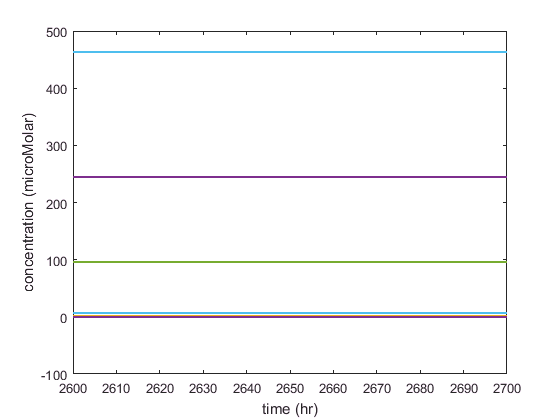

if toplot_timecourse_figs == 1 && timecourse_analysis == 1  
    figure(1)
    plot(t,y,'LineWidth',1.5)
    xlabel('time (hr)')
    ylabel('concentration (microMolar)')
end

    %%% (2) Tracking the change in concentration of protein target for sumoylation (T10 - unsumoylated form; T11 - sumoylated form) 

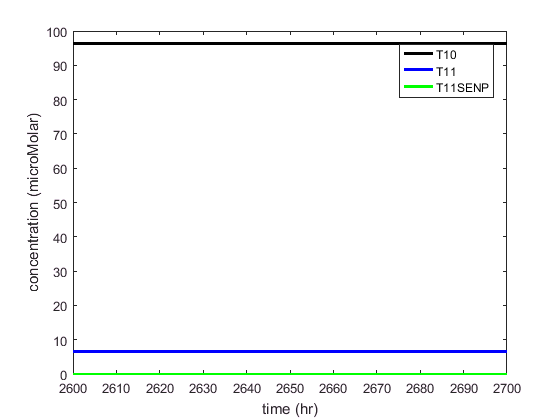

if toplot_timecourse_figs == 1 && timecourse_analysis == 1    
    figure(2)
    plot(t,y(:,nt10),'k',t,y(:,nt11),'b',t,y(:,nt11senp),'g','LineWidth',2)
    xlabel('time (hr)')
    ylabel('concentration (microMolar)')
    legend('T10','T11','T11SENP') 
end

    %%% (3) tracking change in concentration of (free form of) sumo over time

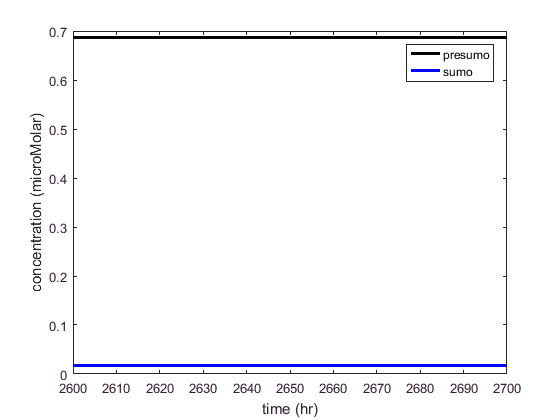

if toplot_timecourse_figs == 1 && timecourse_analysis == 1   
    figure(3)
    plot(t,y(:,npresumo),'k',t,y(:,nsumo),'b','LineWidth',2)
    xlabel('time (hr)')
    ylabel('concentration (microMolar)')
    legend('presumo','sumo')
end

    %%% (4) tracking concentration of the second target; if present

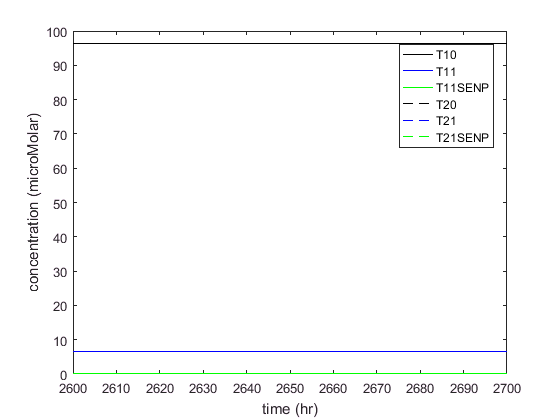

if toplot_timecourse_figs == 1 && timecourse_analysis == 1 
    if systemhas2tars == 1
        figure (4)
        plot(t,y(:,nt10),'k',t,y(:,nt11),'b',t,y(:,nt11senp),'g')
        hold on
        plot(t,y(:,nt20),'--k',t,y(:,nt21),'--b',t,y(:,nt21senp),'--g')
        hold off
        xlabel('time (hr)')
        ylabel('concentration (microMolar)')
        legend('T10','T11','T11SENP','T20','T21','T21SENP')
    end  
end

    %%% (5) tracking concentration of sumoylated E2

if toplot_timecourse_figs == 1 && timecourse_analysis == 1  
    if e2istar == 1
        figure (5)
        plot(t,y(:,ne20),'k',t,y(:,ne21),'b','LineWidth',2)
        xlabel('time (hr)')
        ylabel('concentration (microMolar)')
        legend('E20','E21')
    end
end